clear all
close all

fileName = ['Seq_TICycle(N100to100_NINPS6to20_N_AL20to20_g0.05to0.05_rGGin5to5_rGinGb999to999_Delay0.01to0.01_DNI0.2to0.2_SNI0.4to0.4_TH0.5to0.5)'];
TN = readtable([fileName, '.csv'], 'ReadRowNames',true, 'NumHeaderLines',0,"Delimiter",' ',"EmptyValue",nan);
TN = array2table(table2array(TN)', 'VariableNames',TN.Row)

TN = 8×10 table
    nInp     g      rGGin    rGinGb    Delay    N_AL    DNI    SNI    TH      N 
    ____    ____    _____    ______    _____    ____    ___    ___    ___    ___

      6     0.05       5      999      0.01      20     0.2    0.4    0.5    100
      8      NaN     NaN      NaN       NaN     NaN     NaN    NaN    NaN    NaN
     10      NaN     NaN      NaN       NaN     NaN     NaN    NaN    NaN    NaN
     12      NaN     NaN      NaN       NaN     NaN     NaN    NaN    NaN    NaN
     14      NaN     NaN      NaN       NaN     NaN     NaN    NaN    NaN    NaN
     16      NaN     NaN      NaN       NaN     NaN     NaN    NaN    NaN   

M = 50;

fileName = ['TICycle(N100to100_NINPS6to20_N_AL20to20_g0.05to0.05_rGGin5to5_rGinGb999to999_Delay0.01to0.01_DNI0.2to0.2_SNI0.4to0.4_TH0.5to0.5)']

fileName = 'TICycle(N100to100_NINPS6to20_N_AL20to20_g0.05to0.05_rGGin5to5_rGinGb999to999_Delay0.01to0.01_DNI0.2to0.2_SNI0.4to0.4_TH0.5to0.5)'

T = readtable([fileName, '.csv'])

T = 8×320 table
    nInp     g      rGGin    rGinGb    Delay    N_AL    DNI    SNI    TH      N     MeanANC1    StdANC1     MeanANC2    StdANC2     MeanANC3    StdANC3     MeanANC4    StdANC4     MeanANC5    StdANC5     MeanANC6    StdANC6     MeanANC7    StdANC7     MeanANC8    StdANC8     MeanANC9    StdANC9     MeanANC10    StdANC10    MeanANC11    StdANC11    MeanANC12    StdANC12    MeanANC13    <

voc = 'A':'Z';
hue = (brewermap(12, 'Spectral'));
hue = flip(hue(1:10,:));
SaveFigures = false;


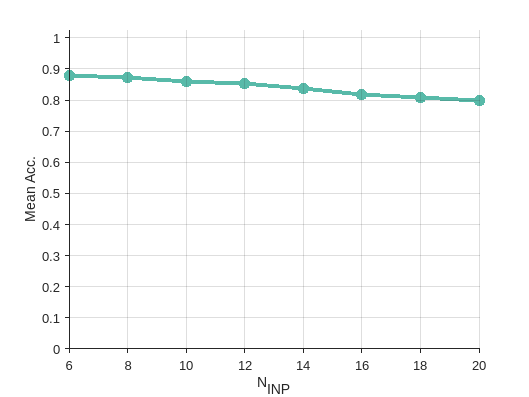

figure

errorbar(T.nInp, T.MeanA, T.StdA/sqrt(M), "Color", hue(1,:), ...
"LineStyle","-", "LineWidth",3,"Marker",".","MarkerSize",30)

ylim([0 1.025])
xlabel('N_{INP}')
ylabel('Mean Acc.')
set(gca,'Layer','top','TickDir','out','Box','off')

grid on

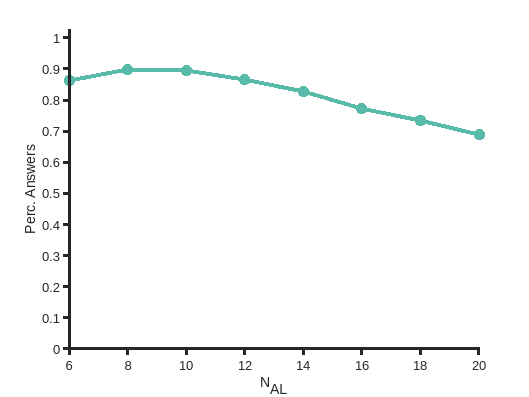

figure

errorbar(T.nInp, T.PercAnsw, T.StdPA/sqrt(M), "Color", hue(1,:), ...
"LineStyle","-", "LineWidth",3,"Marker",".","MarkerSize",30)

ylim([0 1.025])
xlabel('N_{AL}')
ylabel('Perc. Answers')
set(gca,'Layer','top','TickDir','out','Box','off')

grid off
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'PercAnsw');
end

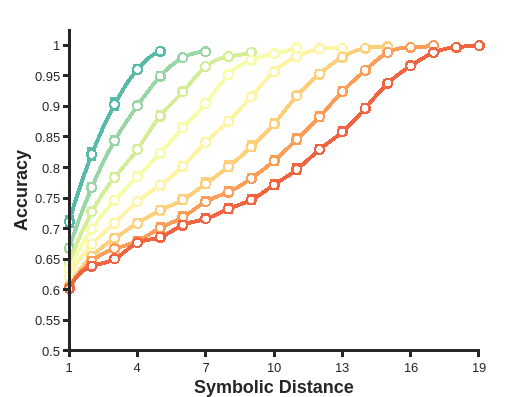


MeanASDs = {T.MeanASD1, T.MeanASD2, T.MeanASD3, T.MeanASD4, T.MeanASD5, T.MeanASD6, T.MeanASD7, T.MeanASD8,...
    T.MeanASD9, T.MeanASD10, T.MeanASD11, T.MeanASD12, T.MeanASD13, T.MeanASD14, T.MeanASD15,...
    T.MeanASD16, T.MeanASD17, T.MeanASD18, T.MeanASD19};

StdASDs = {T.StdASD1, T.StdASD2, T.StdASD3, T.StdASD4, T.StdASD5, T.StdASD6, T.StdASD7, T.StdASD8,...
    T.StdASD9, T.StdASD10, T.StdASD11, T.StdASD12, T.StdASD13, T.StdASD14, T.StdASD15,...
    T.StdASD16, T.StdASD17, T.StdASD18, T.StdASD19};

figure
hold on
for k = 1:numel(TN.nInp)
    if(~isnan(TN.nInp(k)))
        condition1 = (T.nInp == TN.nInp(k));
        
        nsd = TN.nInp(k) - 1;
        ndx = find(condition1);
        acc = nan(1,nsd);
        for r=1:nsd
            ma = MeanASDs{r};
            acc(r) = ma(ndx);
        end
        
        stdAcc = nan(1,nsd);
        for r=1:nsd
            sa = StdASDs{r};
            stdAcc(r) = sa(ndx);
        end        
    
        f = griddedInterpolant(1:nsd,acc,'spline');
        x = 1:0.1:nsd;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:nsd, acc, stdAcc/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"N_{Inp}="+num2str(TN.nInp(k)))
        plot(1:nsd, acc,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")
    end
end

%legend("Location","bestoutside","Box","off")
xticks(1:3:TN.nInp(end)-1)
xlim([1,TN.nInp(end)-1])
%xticklabels(voc')
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
%xlim([0.8 6.2])
ylim([0.5 1.025])


%title("g="+(G) +", g_{b}="+(G/5 /GinGback))
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

if SaveFigures
    hgexport(gcf,'acc');
end

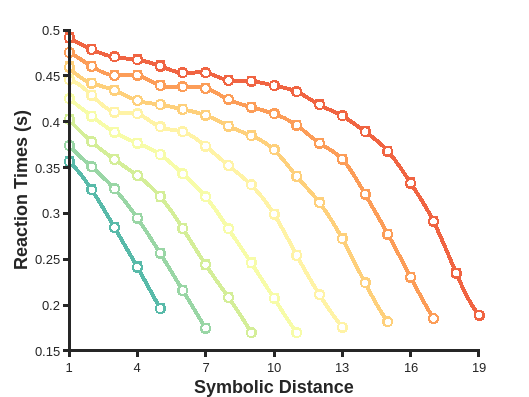

MeanASDs = {T.ReactTimesSD1, T.ReactTimesSD2, T.ReactTimesSD3, T.ReactTimesSD4, T.ReactTimesSD5, T.ReactTimesSD6, T.ReactTimesSD7, T.ReactTimesSD8,...
    T.ReactTimesSD9, T.ReactTimesSD10, T.ReactTimesSD11, T.ReactTimesSD12, T.ReactTimesSD13, T.ReactTimesSD14, T.ReactTimesSD15,...
    T.ReactTimesSD16, T.ReactTimesSD17, T.ReactTimesSD18, T.ReactTimesSD19};

StdASDs = {T.StdRT1, T.StdRT2, T.StdRT3, T.StdRT4, T.StdRT5, T.StdRT6, T.StdRT7, T.StdRT8,...
    T.StdRT9, T.StdRT10, T.StdRT11, T.StdRT12, T.StdRT13, T.StdRT14, T.StdRT15,...
    T.StdRT16, T.StdRT17, T.StdRT18, T.StdRT19};

figure
hold on
for k = 1:numel(TN.nInp)
    if(~isnan(TN.nInp(k)))
        condition1 = (T.nInp == TN.nInp(k));
        
        nsd = TN.nInp(k) - 1;
        ndx = find(condition1);
        rt = nan(1,nsd);
        for r=1:nsd
            ma = MeanASDs{r};
            rt(r) = ma(ndx);
        end
        
        stdRt = nan(1,nsd);
        for r=1:nsd
            sa = StdASDs{r};
            stdRt(r) = sa(ndx);
        end        
    
        f = griddedInterpolant(1:nsd,rt,'spline');
        x = 1:0.1:nsd;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:nsd, rt, stdRt/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"N_{Inp}="+num2str(TN.nInp(k)))
        plot(1:nsd, rt,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")
    end
end

xticks(1:3:TN.nInp(end)-1)
xlim([1,TN.nInp(end)-1])
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Reaction Times (s)',"FontWeight","bold","FontSize",14)

H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

if SaveFigures
    hgexport(gcf,'rt');
end

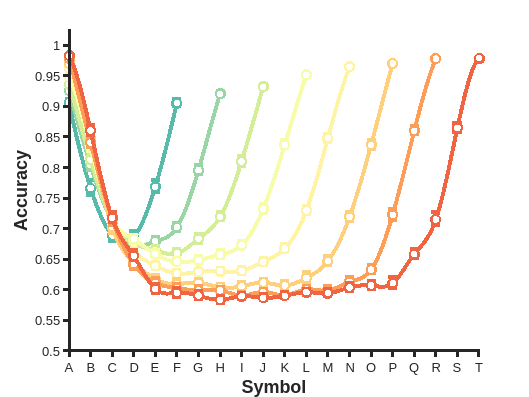

MeanASDs = {T.MeanANC1, T.MeanANC2, T.MeanANC3, T.MeanANC4, T.MeanANC5, T.MeanANC6, T.MeanANC7, T.MeanANC8,...
    T.MeanANC9, T.MeanANC10, T.MeanANC11, T.MeanANC12, T.MeanANC13, T.MeanANC14, T.MeanANC15,...
    T.MeanANC16, T.MeanANC17, T.MeanANC18, T.MeanANC19, T.MeanANC20};

StdASDs = {T.StdANC1, T.StdANC2, T.StdANC3, T.StdANC4, T.StdANC5, T.StdANC6, T.StdANC7, T.StdANC8,...
    T.StdANC9, T.StdANC10, T.StdANC11, T.StdANC12, T.StdANC13, T.StdANC14, T.StdANC15,...
    T.StdANC16, T.StdANC17, T.StdANC18, T.StdANC19, T.StdANC20};

figure
hold on
for k = 1:numel(TN.nInp)
    if(~isnan(TN.nInp(k)))
        condition1 = (T.nInp == TN.nInp(k));
        
        nsd = TN.nInp(k);
        ndx = find(condition1);
        w = nan(1,nsd);
        for r=1:nsd
            ma = MeanASDs{r};
            w(r) = ma(ndx);
        end
        
        stdw = nan(1,nsd);
        for r=1:nsd
            sa = StdASDs{r};
            stdw(r) = sa(ndx);
        end        
    
        f = griddedInterpolant(1:nsd,w,'spline');
        x = 1:0.1:nsd;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:nsd, w, stdw/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"N_{Inp}="+num2str(TN.nInp(k)))
        plot(1:nsd, w,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")
    end
end

%legend("Location","bestoutside","Box","off")
grid off
xticks(1:TN.nInp(end))
xlim([1,TN.nInp(end)])
xticklabels(voc')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('Accuracy',"FontWeight","bold","FontSize",14)
ylim([0.5 1.025])


H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'anc');
end

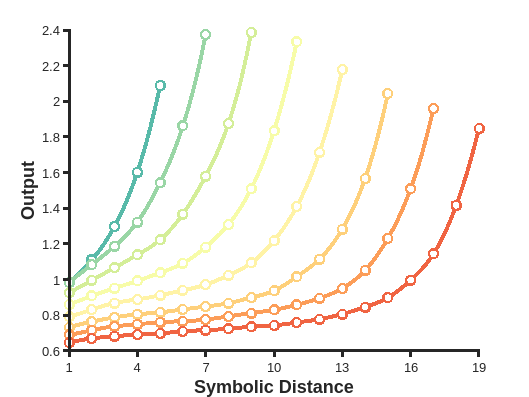

MeanASDs = {T.MaxOutSD1, T.MaxOutSD2, T.MaxOutSD3, T.MaxOutSD4, T.MaxOutSD5, T.MaxOutSD6, T.MaxOutSD7, T.MaxOutSD8,...
    T.MaxOutSD9, T.MaxOutSD10, T.MaxOutSD11, T.MaxOutSD12, T.MaxOutSD13, T.MaxOutSD14, T.MaxOutSD15,...
    T.MaxOutSD16, T.MaxOutSD17, T.MaxOutSD18, T.MaxOutSD19};

StdASDs = {T.StdANC1, T.StdANC2, T.StdANC3, T.StdANC4, T.StdANC5, T.StdANC6, T.StdANC7, T.StdANC8,...
    T.StdANC9, T.StdANC10, T.StdANC11, T.StdANC12, T.StdANC13, T.StdANC14, T.StdANC15,...
    T.StdANC16, T.StdANC17, T.StdANC18, T.StdANC19};

figure
hold on
for k = 1:numel(TN.nInp)
    if(~isnan(TN.nInp(k)))
        condition1 = (T.nInp == TN.nInp(k));
        
        nsd = TN.nInp(k) - 1;
        ndx = find(condition1);
        w = nan(1,nsd);
        for r=1:nsd
            ma = MeanASDs{r};
            w(r) = ma(ndx);
        end
        
        stdw = nan(1,nsd);
        for r=1:nsd
            sa = StdASDs{r};
            stdw(r) = sa(ndx);
        end        
    
        f = griddedInterpolant(1:nsd,w,'spline');
        x = 1:0.1:nsd;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:nsd, w, stdw/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"N_{Inp}="+num2str(TN.nInp(k)))
        plot(1:nsd, w,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")
    end
end

%legend("Location","bestoutside","Box","off")
grid off
xticks(1:3:TN.nInp(end)-1)
xlim([1,TN.nInp(end)-1])
xlabel('Symbolic Distance',"FontWeight","bold","FontSize",14)
ylabel('Output',"FontWeight","bold","FontSize",14)

H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')


if SaveFigures
    hgexport(gcf,'out');
end

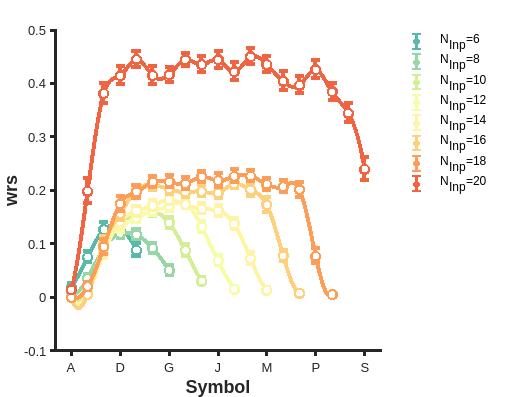

MeanASDs = {T.Wrs1, T.Wrs2, T.Wrs3, T.Wrs4, T.Wrs5, T.Wrs6, T.Wrs7, T.Wrs8,...
    T.Wrs9, T.Wrs10, T.Wrs11, T.Wrs12, T.Wrs13, T.Wrs14, T.Wrs15,...
    T.Wrs16, T.Wrs17, T.Wrs18, T.Wrs19};

StdASDs = {T.StdW1, T.StdW2, T.StdW3, T.StdW4, T.StdW5, T.StdW6, T.StdW7, T.StdW8,...
    T.StdW9, T.StdW10, T.StdW11, T.StdW12, T.StdW13, T.StdW14, T.StdW15,...
    T.StdW16, T.StdW17, T.StdW18, T.StdW19};

figure
hold on
for k = 1:numel(TN.nInp)
    if(~isnan(TN.nInp(k)))
        condition1 = (T.nInp == TN.nInp(k));
        
        nsd = TN.nInp(k) - 1;
        ndx = find(condition1);
        w = nan(1,nsd);
        for r=1:nsd
            ma = MeanASDs{r};
            w(r) = ma(ndx);
        end
        
        stdw = nan(1,nsd);
        for r=1:nsd
            sa = StdASDs{r};
            stdw(r) = sa(ndx);
        end        
    
        f = griddedInterpolant(1:nsd,w,'spline');
        x = 1:0.1:nsd;
        plot(x,f(x),"Color",hue(k,:),"LineWidth", 3,"HandleVisibility","off")
        
        errorbar(1:nsd, w, stdw/sqrt(M),"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 30, "Color", hue(k,:),'DisplayName',"N_{Inp}="+num2str(TN.nInp(k)))
        plot(1:nsd, w,"LineStyle","none", "LineWidth", 3,...
            "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")
    end
end

voc = 'A':'Z';
legend("Location","bestoutside","Box","off")
xticks(1:3:20)
xticklabels(voc(1:3:20)')
xlabel('Symbol',"FontWeight","bold","FontSize",14)
ylabel('wrs',"FontWeight","bold","FontSize",14)

H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')

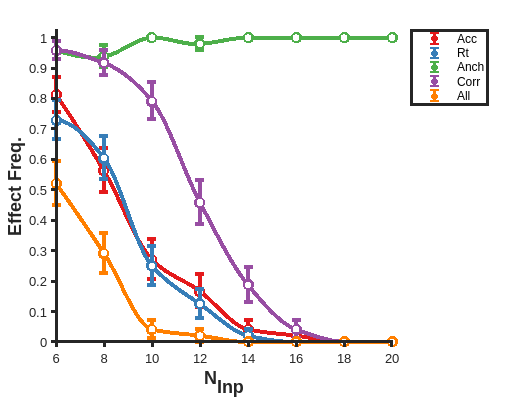

colors = brewermap(5,'Set1');
voc = 'A':'Z';

TH = 0.5;

figure
hold on

condition1 = (T.TH == TH);

ndx = find(condition1);

interp_mode = "makima";
Ns = T.nInp(ndx);
f = griddedInterpolant(Ns,T.MBA(ndx),interp_mode);
x = Ns(1):0.05:Ns(end);
plot(x,f(x),"Color",colors(1,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBA(ndx), T.StdMBA(ndx)/sqrt(M), "Color", colors(1,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Acc')
plot(Ns, T.MBA(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(Ns,T.MBRt(ndx),interp_mode);
plot(x,f(x),"Color",colors(2,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBRt(ndx), T.StdMBRt(ndx)/sqrt(M), "Color", colors(2,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Rt')
plot(Ns, T.MBRt(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(Ns,T.MBANC(ndx),interp_mode);
plot(x,f(x),"Color",colors(3,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBANC(ndx), T.StdMBANC(ndx)/sqrt(M), "Color", colors(3,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Anch')
plot(Ns, T.MBANC(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

f = griddedInterpolant(Ns,T.MBCorr(ndx),interp_mode);
plot(x,f(x),"Color",colors(4,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBCorr(ndx), T.StdMBCorr(ndx)/sqrt(M), "Color", colors(4,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'Corr')
plot(Ns, T.MBCorr(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")


f = griddedInterpolant(Ns,T.MBAll(ndx),interp_mode);
plot(x,f(x),"Color",colors(5,:),"LineWidth", 3,"HandleVisibility","off")
errorbar(Ns, T.MBAll(ndx), T.StdMBAll(ndx)/sqrt(M), "Color", colors(5,:), ...
"LineStyle","none", "LineWidth",3,"Marker",".","MarkerSize",30, "DisplayName", 'All')
plot(Ns, T.MBAll(ndx),"LineStyle","none", "LineWidth", 3,...
    "Marker", ".", "MarkerSize", 12, "Color", 'w',"HandleVisibility","off")

%set(gca, 'XScale', 'log')
legend('Location','bestoutside')

ylim([0 1.025])
xlabel('N_{Inp}',"FontWeight","bold","FontSize",14)
ylabel('Effect Freq.',"FontWeight","bold","FontSize",14)
H=gca;
H.LineWidth=2.5;
set(gca,'Layer','top','TickDir','out','Box','off')